# Suspension Kinemaics Test

## Point Definitions

chas_lower_front = [398.914 -156.064 67.743];  % const.
chas_lower_rear = [599.771 -153.063 76.107];  % const.
upright_lower = [479.41 -588.899 73];
a_arm_lower = [chas_lower_front; upright_lower; chas_lower_rear];

chas_upper_front = [395.756 -259.077 245.545];  % const.
chas_upper_rear = [617.179 -287.046 245.545];  % const.
upright_upper = [504.31 -570 295];
a_arm_upper = [chas_upper_front; upright_upper; chas_upper_rear];

% Suspension height change
heave = 50;

## Calculating Distances

% Length of the a-arms
[l_front_1, l_rear_1] = length_a_Arm(a_arm_upper); % const.
[l_front_2, l_rear_2] = length_a_Arm(a_arm_lower); % const.

% Distance between upright a-arm attachments
uprightDistance = distance2points(upright_lower, upright_upper); % const.



## Calculating new position

% Calculate minimum distance between (chassis) a-arm axis and upright attachment point 
% point_to_line(upright_upper, chas_upper_front, chas_upper_rear);

%
a = chas_upper_front';
u = (chas_upper_front' - chas_upper_rear') / norm(chas_upper_front' - chas_upper_rear');
p = upright_upper';

kf = dot(p-a, u) / dot(u,u);
f = a + kf * u;
d = norm(p-f);

% Get new point
b = chas_upper_rear;
alpha = asin(heave/d);
p_new=rot3dvect(p,[a b'],alpha);

a_arm_upper_new = [chas_upper_front; p_new'; chas_upper_rear];


% with function
posNew = calculate_aarmPosition(chas_lower_front, chas_lower_rear, upright_lower, heave)

posNew =   481.4510
 -586.2288
   23.0295


a_arm_lower_new = [chas_lower_front; posNew'; chas_lower_rear];

%lower_circ = bsxfun(@plus, chas_upper_front', a*cos(theta)*lower_length + b*sin(theta)*lower_length)';

% Error in %
calcError = abs(distance2points(p_new, posNew) - uprightDistance)/uprightDistance*100

calcError = 0.3458

% Error in mm
abs(distance2points(p_new, posNew) - uprightDistance)

ans = 0.7753


% transform new position
a_arm_upper_new = a_arm_upper_new + [0 0 heave];
a_arm_lower_new = a_arm_lower_new + [0 0 heave];

## Plotting the results

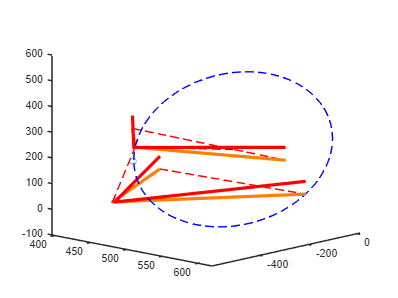

plotSuspension(a_arm_upper)
hold on
plotSuspension(a_arm_lower)

% distance outer a-arm bearings
plot3([upright_lower(1) upright_upper(1)], [upright_lower(2) upright_upper(2)], [upright_lower(3) upright_upper(3)],'--','Color','red')

% upper a-arm axis
plot3([chas_upper_front(1) chas_upper_rear(1)], [chas_upper_front(2) chas_upper_rear(2)], [chas_upper_front(3) chas_upper_rear(3)],'--','Color','red')

% lower a-arm axis
plot3([chas_lower_front(1) chas_lower_rear(1)], [chas_lower_front(2) chas_lower_rear(2)], [chas_lower_front(3) chas_lower_rear(3)],'--','Color','red')

% Plot the normal from the a-arm axis to the upright
plot3([f(1) upright_upper(1)],[f(2) upright_upper(2)],[f(3) upright_upper(3)],'--','Color','blue')

% Plot the movement circle
circleUpper = drawCircle(d,f,u,'blue','--');

% New suspension point 
scatter3(p_new(1),p_new(2),p_new(3));
plotSuspension(a_arm_upper_new,'red');
plotSuspension(a_arm_lower_new,'red');

function plotSuspension(a_arm,color)
    if nargin == 1
        color = [1 0.5 0];
    end

    x = a_arm(:,1);
    y = a_arm(:,2);
    z = a_arm(:,3);
    plot3(x,y,z,'Color',color,'LineWidth',3);
end

function [l1, l2] = length_a_Arm(a_arm)
    l1 = sqrt((a_arm(1,1) - a_arm(2,1)) ^ 2 + (a_arm(1,2) - a_arm(2,2)) ^ 2 + (a_arm(1,3) - a_arm(2,3))^2);
    l2 = sqrt((a_arm(3,1) - a_arm(2,1)) ^ 2 + (a_arm(3,2) - a_arm(2,2)) ^ 2 + (a_arm(3,3) - a_arm(2,3))^2);
end

function distance = distance2points(p1, p2)
    distance = sqrt((p1(1) - p2(1)) ^ 2 + (p1(2) - p2(2)) ^ 2 + (p1(3) - p2(3)) ^ 2);
end

function d = point_to_line(pt, v1, v2)
  a = v1 - v2;
  b = pt - v2;
  d = norm(cross(a,b)) / norm(a);
end

function circle = drawCircle(rad,pos,n,color,options)
    %https://demonstrations.wolfram.com/ParametricEquationOfACircleIn3D/
    %draws a 3D circle at position pos with radius rad, normal to the
    %circle n, and color color.
    phi = atan2(n(2),n(1)); %azimuth angle, in [-pi, pi]
    theta = atan2(sqrt(n(1)^2 + n(2)^2) ,n(3));% zenith angle, in [0,pi]    
    t = 0:pi/32:2*pi;
    x = pos(1)- rad*( cos(t)*sin(phi) + sin(t)*cos(theta)*cos(phi) );
    y = pos(2)+ rad*( cos(t)*cos(phi) - sin(t)*cos(theta)*sin(phi) );
    z = pos(3)+ rad*sin(t)*sin(theta);
    plot3(x,y,z,options,'Color',color)
    circle = [x' y' z'];
end

function V=rot3dvect(U,rotaxis,phi);
     % rot3dvect
     %           rotate points U by the angle phi around axis rotaxis
     %
     %           V=rot3dvect(U,rotaxis,phi);
     %
     %
     %           U : real matrix with 3 rows and any column size. Each column contains one point.
     %               1st row = x, 2nd row = y, 3rd row = z.
     %
     %     rotaxis : the rotation axis, defined by two points, which are combined in a 3 x 2 matrix.
     %               Each column contains one point
     %
     %         phi : a scalar, contining the rotation angle in radian.
     %
     %           V : the points U after rotaion.
     %
     %   Example:
     %              U=eye(3,3);             % Points on x-, y- and z-axis
     %              rotaxis=[0,1;0,1;0,1];  % rotation axis through points [0;0;0] and [1;1;1]
     %              V=rot3dvect(U,rotaxis,%pi); % rotate the three points by 180° around rotation axis.
     %
    
    n0=rotaxis(:,1);
    n1=rotaxis(:,2);
    
    nn=n1 - n0;
    nn=nn ./sqrt(nn.' * nn);   % normierte Rotationsachse
    
    % Verschiebung in den Ursprung
    [tmpvar,vc]=meshgrid(1:1:size(U,2),n0);
    U=U - vc;
    
    % Create Rotation Matrix
    v1=nn(1); v2=nn(2); v3=nn(3);
    R=zeros(3,3);
    R(1,1)=cos(phi) + (v1 .^2) .*(1-cos(phi));
    R(2,2)=cos(phi) + (v2 .^2) .*(1-cos(phi));
    R(3,3)=cos(phi) + (v3 .^2) .*(1-cos(phi));
    R(1,2)=v1 .*v2 .*(1 - cos(phi)) - v3 .*sin(phi);
    R(1,3)=v1 .*v3 .*(1 - cos(phi)) + v2 .*sin(phi);
    
    R(2,1)=v1 .*v2 .*(1 - cos(phi)) + v3 .*sin(phi);
    R(2,3)=v2 .*v3 .*(1 - cos(phi)) - v1 .*sin(phi);
    
    R(3,1)=v1 .*v3 .*(1 - cos(phi)) - v2 .*sin(phi);
    R(3,2)=v2 .*v3 .*(1 - cos(phi)) + v1 .*sin(phi);
    
    % Perform Rotation
    U=R*U;
    % move back to original coordinate system
    V=U + vc;
end

function posNew = calculate_aarmPosition(chas_front, chas_rear, upright, heave)
    % chassis points
    a = chas_front';
    b = chas_rear;
    
    % direction normal vector
    u = (chas_front' - chas_rear') / norm(chas_front' - chas_rear');
    p = upright';
    
    kf = dot(p-a, u) / dot(u,u);
    f = a + kf * u;
    d = norm(p-f);
    
    % Get new point
    alpha = asin(heave/d);              % calculate angle from old possition to new position
    posNew=rot3dvect(p,[a b'],alpha);   % rotate a-arm (
end